clear;  ccc='%3A';
%close all
%---setting
expri='ens02';   member=1:10;    lev=10;   yi=22;  xi=100;
%year='2007'; mon='06'; date='01';
year='2018'; mon='06'; date='21';  hr=22;  minu='40';  dom='01';
%year='2008'; mon='06'; date='16';  hr=2;  minu='00';  dom='02';
dirmem='pert'; infilenam='wrfout';  

%indir=['/HDD003/pwin/Experiments/expri_ens200323/',expri];
indir=['E:/wrfout/expri_ens200323/',expri];
%indir='E:/wrfout/largens';
outdir='E:/figures/ens200323';


titnam='KE spectral';   fignam=[expri,'_KE-sptrl_'];

ti=hr;
s_hr=num2str(ti,'%.2d');  % start time string
nmi=0;
u.mean=0;  v.mean=0;
for mi=member
nmi=nmi+1;
nen=num2str(mi,'%.2d');
infile=[indir,'/',dirmem,nen,'/',infilenam,'_d',dom,'_',year,'-',mon,'-',date,'_',s_hr,ccc,minu,ccc,'00'];
%infile=[indir,'/',infilenam,'_d',dom,'_',year,'-',mon,'-',date,'_',s_hr,ccc,minu,ccc,'00_',nen];
%------read netcdf data--------
u.stag = ncread(infile,'U');u.stag=double(u.stag);
v.stag = ncread(infile,'V');v.stag=double(v.stag);
u.mean=u.mean+u.stag/length(member);
v.mean=v.mean+v.stag/length(member);
%---
%uunstag(:,nmi)=(u.stag(1:end-1,yi,lev)+u.stag(2:end,yi,lev))*0.5;
%vunstag(:,nmi)=(v.stag(:,yi,lev)+v.stag(:,yi+1,lev))*0.5;
uunstag(:,nmi)=(u.stag(xi,:,lev)+u.stag(xi+1,:,lev))*0.5;
vunstag(:,nmi)=(v.stag(xi,1:end-1,lev)+v.stag(xi,2:end,lev))*0.5;
end

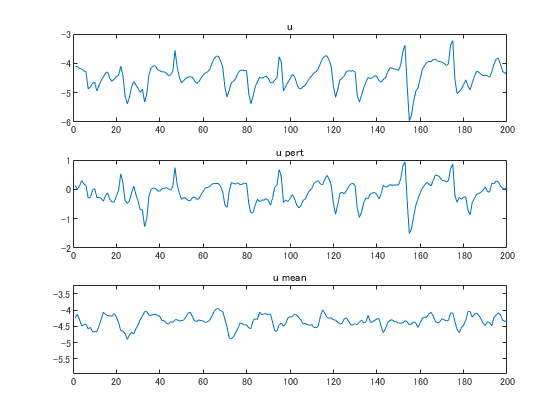

umean=mean(uunstag,2);
vmean=mean(vunstag,2);
%umean=uunstag(:,2);
%vmean=vunstag(:,2);

nx=length(umean);
%
upert=uunstag-repmat(umean,1,length(member));
vpert=vunstag-repmat(vmean,1,length(member));

figure
mmi=1;
subplot(3,1,1)
plot(uunstag(:,mmi))
title('u')
%set(gca,'YLim',[min(uunstag(:,mmi)) max(uunstag(:,mmi)) ])
subplot(3,1,2)
plot(upert(:,mmi))
title('u pert')
subplot(3,1,3)
plot(umean)
title('u mean')
set(gca,'YLim',[min(uunstag(:,mmi)) max(uunstag(:,mmi)) ])

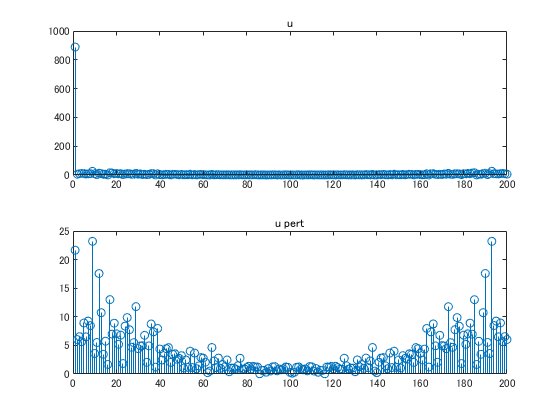

ufft1=fft(uunstag(:,mmi));
vfft1=fft(vunstag(:,mmi));
%ufft1(1)=0; vfft1(1)=0; 
%
upfft1=fft(upert(:,mmi));
vpfft1=fft(vpert(:,mmi));
%
figure
subplot(2,1,1)
stem(abs(ufft1))
title('u')
%set(gca,'XLim',[1 nx/2-1],'YLim',[1 1e3],'YScale', 'log')
subplot(2,1,2)
stem(abs(upfft1))
title('u pert')

%set(gca,'XLim',[1 nx/2-1],'YLim',[1 1e3],'YScale', 'log')

% Fs = 100;            % Sampling frequency                    
% T = 1/Fs;             % Sampling period       
% L = 500;             % Length of signal
% t = (0:L-1)*T;        % Time vector
% S = 1.2*sin(2*pi*50*t) + 1.5*cos(2*pi*120*t);
% X = S + 5*randn(size(t));
% Xmean=mean(X);
% Xpert=X-Xmean;
% 
% xfft1=fft(X);
% xpfft1=fft(Xpert);
% 
% figure
% subplot(3,1,1)
% plot(X)
% subplot(3,1,2)
% stem(abs(xfft1/L)*2)
% subplot(3,1,3)
% plot(abs(xfft1/L)); hold on
% plot(abs(xpfft1/L))

KEu=abs(ufft1).^2;
KEv=abs(vfft1).^2;
KE=(KEu+KEv);
%KEmean=mean(KE,2);

KEup=abs(upfft1).^2;
KEvp=real(vpfft1).^2+imag(vpfft1).^2;
KEp=(KEup+KEvp);
%KEpmean=mean(KEp,2);

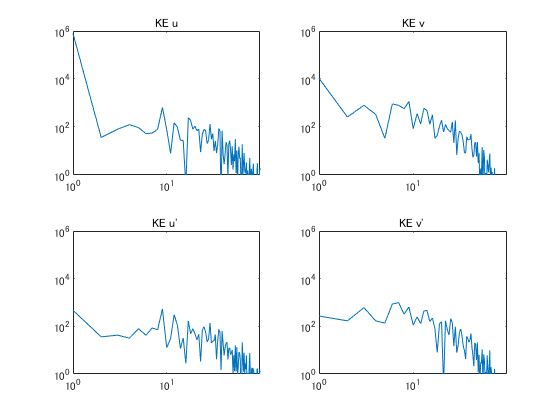


figure
subplot(2,2,1)
plot(KEu)
title('KE u')
set(gca,'XLim',[1 nx/2-1],'YLim',[1 1e6],'YScale', 'log','XScale', 'log')
%set(gca,'YScale', 'log','XScale', 'log')

subplot(2,2,2)
plot(KEv)
title('KE v')
set(gca,'XLim',[1 nx/2-1],'YLim',[1 1e6],'YScale', 'log','XScale', 'log')
%set(gca,'YScale', 'log','XScale', 'log')

subplot(2,2,3)
plot(KEup)
title("KE u' ")
set(gca,'XLim',[1 nx/2-1],'YLim',[1 1e6],'YScale', 'log','XScale', 'log')
%set(gca,'YScale', 'log','XScale', 'log')

subplot(2,2,4)
plot(KEvp)
title("KE v' ")
set(gca,'XLim',[1 nx/2-1],'YLim',[1 1e6],'YScale', 'log','XScale', 'log')

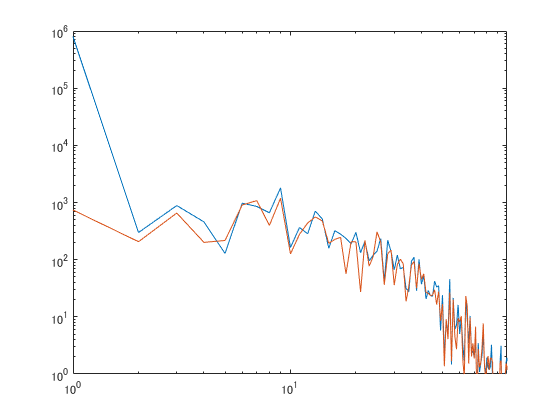

%set(gca,'YScale', 'log','XScale', 'log')
figure
plot(KE); hold on
plot(KEp)
set(gca,'XLim',[1 nx/2-1],'YLim',[1 1e6],'YScale', 'log','XScale', 'log')

%set(gca,'YScale', 'log','XScale', 'log')